# Alpha Dataset

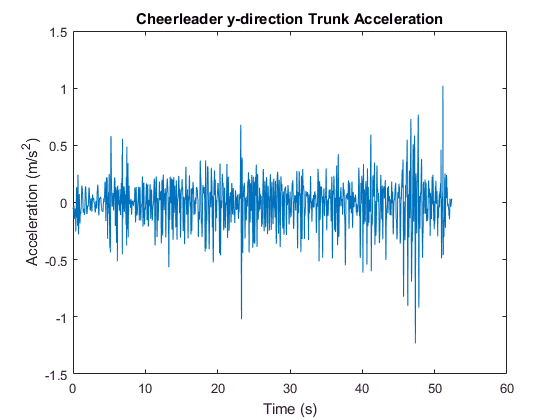

load cheerleadertrunk.mat
Fs = 100;
t_omi = linspace(0,length(cheerleaderomi(:,1))/Fs,length(cheerleaderomi(:,1)));
plot(t_omi,cheerleaderomi(:,5))
title('Cheerleader y-direction Trunk Acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

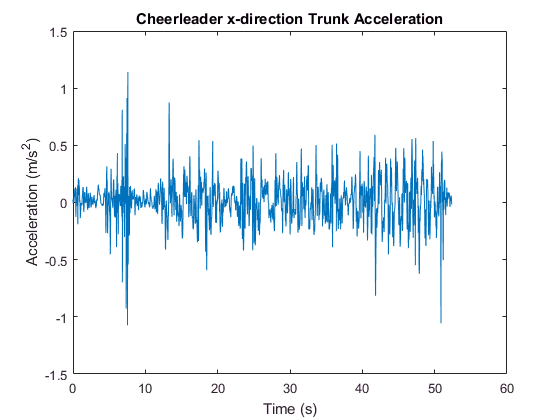

plot(t_omi,cheerleaderomi(:,6))
title('Cheerleader x-direction Trunk Acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

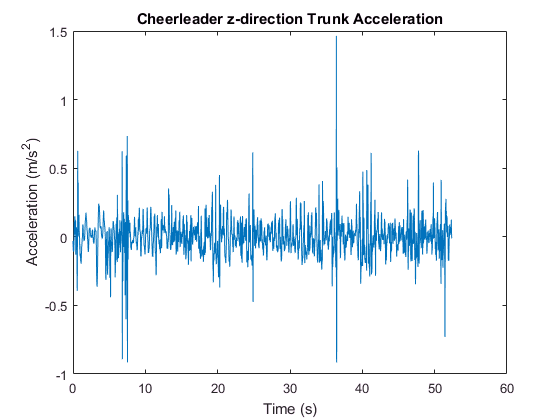

plot(t_omi,cheerleaderomi(:,7))
title('Cheerleader z-direction Trunk Acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

mean(abs(cheerleaderomi(:,5)))

ans = 0.1261

mean(abs(cheerleaderomi(:,6)))

ans = 0.1239

mean(abs(cheerleaderomi(:,7)))

ans = 0.0869

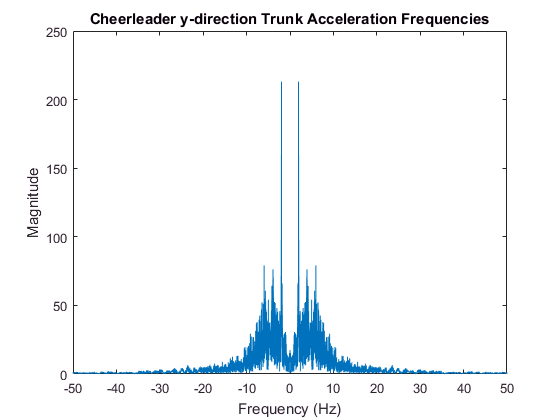

N_omi = length(cheerleaderomi(:,1));
f_omi = linspace(-Fs/2, Fs/2 - Fs/N_omi, N_omi) + Fs/(2*N_omi)*mod(N_omi,2);
plot(f_omi,fftshift(abs(fft(cheerleaderomi(:,5)))));
title('Cheerleader y-direction Trunk Acceleration Frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

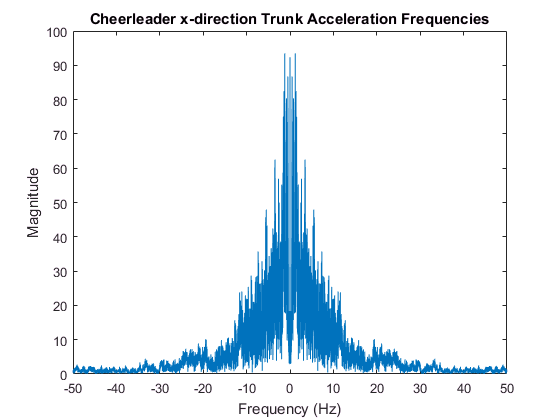

plot(f_omi,fftshift(abs(fft(cheerleaderomi(:,6)))));
title('Cheerleader x-direction Trunk Acceleration Frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

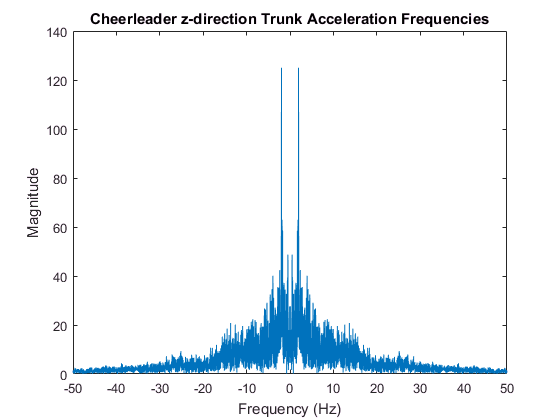

plot(f_omi,fftshift(abs(fft(cheerleaderomi(:,7)))));
title('Cheerleader z-direction Trunk Acceleration Frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

[freq_cy,mag_cy,bpm_cy] = findbpm('cheerleadertrunk.mat',Fs)

freq_cy =   -50.0000  -49.9809  -49.9618  -49.9427  -49.9236  -49.9045  -49.8854  -49.8663  -49.8472  -49.8281  -49.8090  -49.7899  -49.7708  -49.7517  -49.7326  -49.7135  -49.6944  -49.6753  -49.6562  -49.6371  -49.6180  -49.5989  -49.5798  -49.5607  -49.5416  -49.5225  -49.5034  -49.4843  -49.4652  -49.4461  -49.4270  -49.4079  -49.3888  -49.3697  -49.3506  -49.3316  -49.3125  -49.2934  -49.2743  -49.2552  -49.2361  -49.2170  -49.1979  -49.1788  -49.1597  -49.1406  -49.1215  -49.1024  -49.0833  -49.0642


mag_cy =     0.4540
    0.5349
    1.0366
    1.1380
    1.1754
    0.4006
    0.2843
    0.3838
    0.9914
    0.8934


bpm_cy = 118.0290

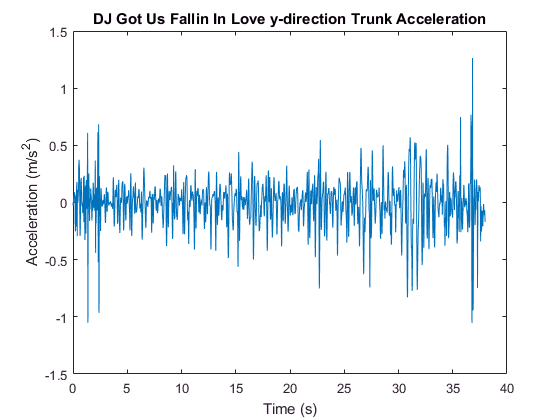

load ushertrunk.mat
Fs = 100;
t_usher = linspace(0,length(usher(:,1))/Fs,length(usher(:,1)));
plot(t_usher,usher(:,5))
title('DJ Got Us Fallin In Love y-direction Trunk Acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

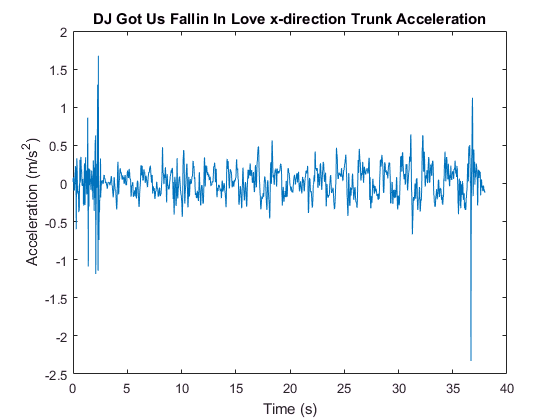

plot(t_usher,usher(:,6))
title('DJ Got Us Fallin In Love x-direction Trunk Acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

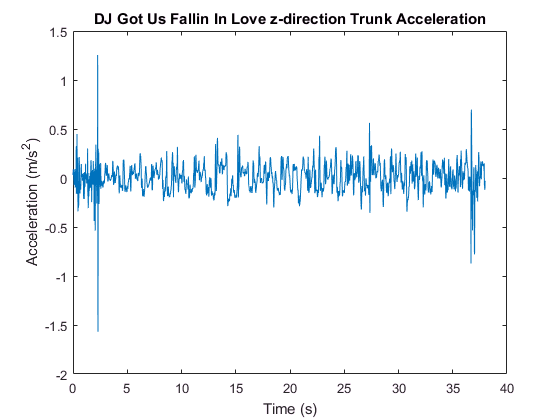

plot(t_usher,usher(:,7))
title('DJ Got Us Fallin In Love z-direction Trunk Acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)');

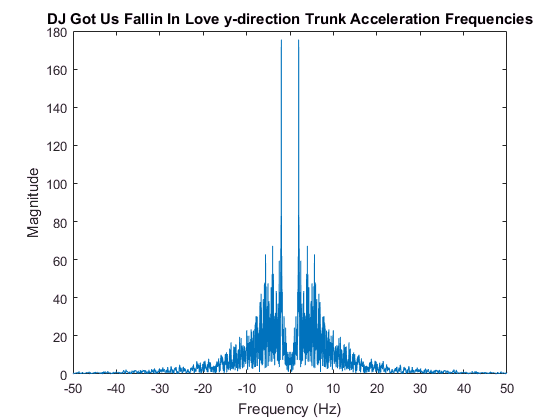

N_usher = length(usher(:,1));
f_usher = linspace(-Fs/2, Fs/2 - Fs/N_usher, N_usher) + Fs/(2*N_usher)*mod(N_usher,2);
plot(f_usher,fftshift(abs(fft(usher(:,5)))));
title('DJ Got Us Fallin In Love y-direction Trunk Acceleration Frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

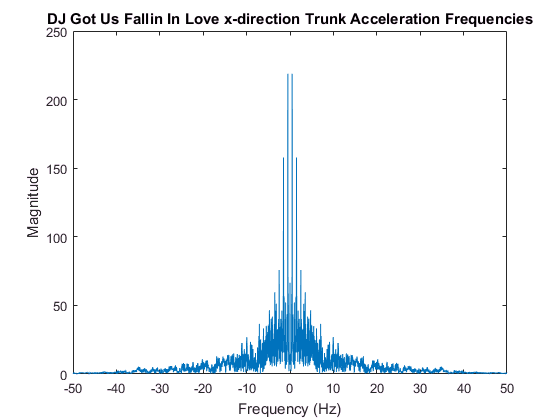

plot(f_usher,fftshift(abs(fft(usher(:,6)))));
title('DJ Got Us Fallin In Love x-direction Trunk Acceleration Frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

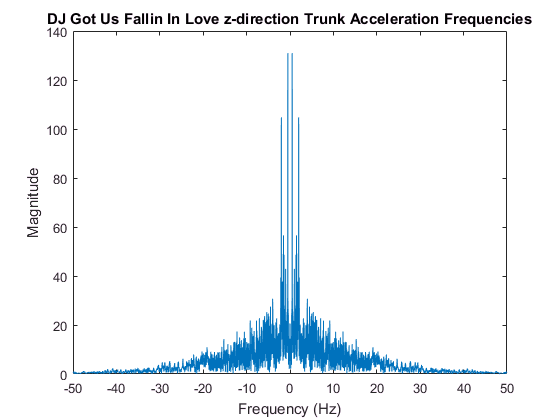

plot(f_usher,fftshift(abs(fft(usher(:,7)))));
title('DJ Got Us Fallin In Love z-direction Trunk Acceleration Frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

[freq_uy,mag_uy,bpm_uy] = findbpm('ushertrunk.mat',Fs)

freq_uy =   -50.0000  -49.9737  -49.9473  -49.9210  -49.8947  -49.8684  -49.8420  -49.8157  -49.7894  -49.7630  -49.7367  -49.7104  -49.6840  -49.6577  -49.6314  -49.6051  -49.5787  -49.5524  -49.5261  -49.4997  -49.4734  -49.4471  -49.4207  -49.3944  -49.3681  -49.3418  -49.3154  -49.2891  -49.2628  -49.2364  -49.2101  -49.1838  -49.1575  -49.1311  -49.1048  -49.0785  -49.0521  -49.0258  -48.9995  -48.9731  -48.9468  -48.9205  -48.8942  -48.8678  -48.8415  -48.8152  -48.7888  -48.7625  -48.7362  -48.7098


mag_uy =     0.3384
    0.3934
    0.4951
    0.5186
    0.5809
    0.5638
    0.4096
    0.3024
    0.2483
    0.1995


bpm_uy = 120.0632

load bonfiretrunk.mat
N_bonfire = length(bonfire(:,1));
t_bonfire = linspace(0,N_bonfire/Fs,N_bonfire);
f_bonfire = linspace(-Fs/2, Fs/2 - Fs/N_bonfire, N_bonfire) + Fs/(2*N_bonfire)*mod(N_bonfire,2);
[freq_bty,mag_bty,bpm_bty] = findbpm('bonfiretrunk.mat',Fs)

freq_bty =   -50.0000  -49.9762  -49.9525  -49.9287  -49.9049  -49.8812  -49.8574  -49.8337  -49.8099  -49.7861  -49.7624  -49.7386  -49.7148  -49.6911  -49.6673  -49.6435  -49.6198  -49.5960  -49.5722  -49.5485  -49.5247  -49.5010  -49.4772  -49.4534  -49.4297  -49.4059  -49.3821  -49.3584  -49.3346  -49.3108  -49.2871  -49.2633  -49.2395  -49.2158  -49.1920  -49.1683  -49.1445  -49.1207  -49.0970  -49.0732  -49.0494  -49.0257  -49.0019  -48.9781  -48.9544  -48.9306  -48.9068  -48.8831  -48.8593  -48.8356


mag_bty =     0.1054
    0.2541
    0.1907
    0.2950
    0.1536
    0.2918
    0.2220
    0.2847
    0.1534
    0.2665


bpm_bty = 161.1217

load bonfirearm.mat
N_bonfirehand = length(bonfirehand(:,1));
t_bonfirehand = linspace(0,N_bonfirehand/Fs,N_bonfirehand);
f_bonfirehand = linspace(-Fs/2, Fs/2 - Fs/N_bonfirehand, N_bonfirehand) + Fs/(2*N_bonfirehand)*mod(N_bonfirehand,2);
[freq_bay,mag_bay,bpm_bay] = findbpm('bonfirearm.mat',Fs)

freq_bay =   -49.9923  -49.9768  -49.9613  -49.9458  -49.9304  -49.9149  -49.8994  -49.8840  -49.8685  -49.8530  -49.8375  -49.8221  -49.8066  -49.7911  -49.7756  -49.7602  -49.7447  -49.7292  -49.7138  -49.6983  -49.6828  -49.6673  -49.6519  -49.6364  -49.6209  -49.6054  -49.5900  -49.5745  -49.5590  -49.5436  -49.5281  -49.5126  -49.4971  -49.4817  -49.4662  -49.4507  -49.4352  -49.4198  -49.4043  -49.3888  -49.3734  -49.3579  -49.3424  -49.3269  -49.3115  -49.2960  -49.2805  -49.2650  -49.2496  -49.2341


mag_bay =     0.1753
    0.5854
    0.1439
    0.3885
    0.2118
    0.1154
    0.0513
    0.0376
    0.0304
    0.2079


bpm_bay = 161.5349

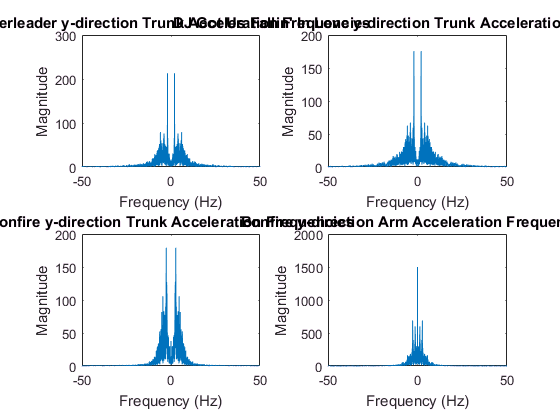

figure
subplot(2,2,1)
plot(f_omi,fftshift(abs(fft(cheerleaderomi(:,5)))));
title('Cheerleader y-direction Trunk Acceleration Frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
subplot(2,2,2)
plot(f_usher,fftshift(abs(fft(usher(:,5)))));
title("DJ Got Us Fallin' In Love y-direction Trunk Acceleration Frequencies")
xlabel('Frequency (Hz)')
ylabel('Magnitude')
subplot(2,2,3)
plot(f_bonfire, fftshift(abs(fft(bonfire(:,5)))));
title("Bonfire y-direction Trunk Acceleration Frequencies")
xlabel('Frequency (Hz)')
ylabel('Magnitude')
subplot(2,2,4)
plot(f_bonfirehand, fftshift(abs(fft(bonfirehand(:,5)))));
title('Bonfire y-direction Arm Acceleration Frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

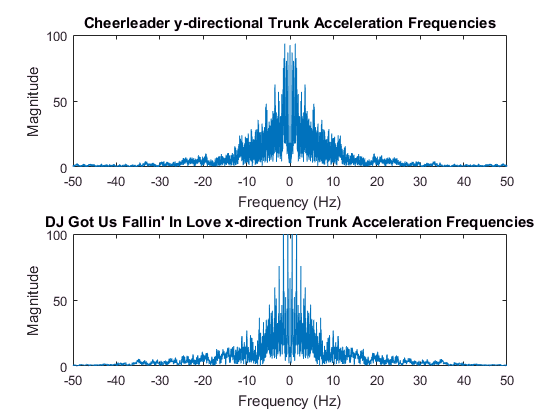

figure
subplot(2,1,1)
plot(f_omi,fftshift(abs(fft(cheerleaderomi(:,6)))));
title('Cheerleader y-directional Trunk Acceleration Frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
subplot(2,1,2)
plot(f_usher,fftshift(abs(fft(usher(:,6)))));
ylim([0, 100])
title("DJ Got Us Fallin' In Love x-direction Trunk Acceleration Frequencies")
xlabel('Frequency (Hz)')
ylabel('Magnitude')

We went backwards to validate our data. We found two songs that have very similar BPM and then attached the accelerometer to a dancer's hip and collected data. We took the FFT of this data and compared it to each other, and found that the data looked very similar, especially in the side-to-side direction. This validated the concept that people dancing to songs with similar bpms will show similar accelerations/frequencies. The goal would now be to figure out ways to relate acceleration to bpm.

[f_omi, mag_omi, bpm_omi] = findbpm('cheerleadertrunk.mat', 100)

f_omi =   -50.0000  -49.9809  -49.9618  -49.9427  -49.9236  -49.9045  -49.8854  -49.8663  -49.8472  -49.8281  -49.8090  -49.7899  -49.7708  -49.7517  -49.7326  -49.7135  -49.6944  -49.6753  -49.6562  -49.6371  -49.6180  -49.5989  -49.5798  -49.5607  -49.5416  -49.5225  -49.5034  -49.4843  -49.4652  -49.4461  -49.4270  -49.4079  -49.3888  -49.3697  -49.3506  -49.3316  -49.3125  -49.2934  -49.2743  -49.2552  -49.2361  -49.2170  -49.1979  -49.1788  -49.1597  -49.1406  -49.1215  -49.1024  -49.0833  -49.0642


mag_omi =     0.4540
    0.5349
    1.0366
    1.1380
    1.1754
    0.4006
    0.2843
    0.3838
    0.9914
    0.8934


bpm_omi = 118.0290

figure
plot(f_omi,mag_omi)
title('Cheerleader y-direction Trunk Acceleration Frequencies')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

function [f, mag, bpm] = findbpm(filename, Fs)
    file = cell2mat(struct2cell(load(filename)));
    N = length(file(:,1));
    f = linspace(-Fs/2, Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N,2);
    mag = fftshift(abs(fft(file(:,5))));
    
    positive = mag(f > 0.3);
    H = max(positive);
    bps = find(mag == H);
    bpm = abs(f(bps(1)))*60;
end
